## Wing Design

clear
% % Set default figure size (in inches)
% set(groot, 'defaultFigureUnits', 'inches');
% set(groot, 'defaultFigurePosition', [1, 1, 6, 4]); % Width = 6 inches, Height = 4 inches
% 
% % Set default font settings for all text in plots
% set(groot, 'defaultAxesFontName', 'Times New Roman');
% set(groot, 'defaultAxesFontSize', 12); % Font size for axis labels and ticks
% set(groot, 'defaultTextFontSize', 12); % Font size for text in the plot
% set(groot, 'defaultAxesTitleFontSizeMultiplier', 1.2); % Slightly larger title
% set(groot, 'defaultLegendFontSize', 11); % Font size for legend text
% 
% % Set default line and marker settings
% set(groot, 'defaultLineLineWidth', 1.5); % Default line width
% set(groot, 'defaultLineMarkerSize', 8); % Default marker size
% 
% % Set default box and grid
% set(groot, 'defaultAxesBox', 'on'); % Enable box around plots by default
% set(groot, 'defaultAxesGridLineStyle', '-'); % Solid grid lines
% set(groot, 'defaultAxesXGrid', 'on'); % Enable grid for X axis
% set(groot, 'defaultAxesYGrid', 'on'); % Enable grid for Y axis

global airfoil cruise1 cruise2 C_cruise Wto Swet_SrefWing Swet_SrefBody l_d bdes bodyDiameter bodyLength Srefdes Damping tolerance Wpay W_ZF_Nowing W_Sdes Ww nult Wpayload
Wpay = 8.7176e3*9.81;
%W_ZF_Nowing = 389900 * 9.81;% guess
bodyDiameter = 6.38;
Damping = 0.03;
tolerance = 1e-4;
cruise1 = AirCondition();
cruise1.M = 0.83;
cruise1.h = convlength(38000, 'ft','m');

cruise2 = AirCondition();
cruise2.V = convvel(400, 'kts', 'm/s');
cruise2.h = convlength(18000, 'ft','m');
cruise2 = cruise2.calcM();

C_cruise = 0.5 ./ 3600;
W_Sdes = 7683;
Srefdes = 548.7;
Swet_SrefWing = 2.2;
bodyLength = 80;
Swet_SrefBody = pi*bodyDiameter*bodyLength*1.1/Srefdes;
l_d = 78/bodyDiameter;

nult = 3.8;
%Initial guess
Wto0 = 4.299e5*9.81;
Wpayload = 8.7176e3*9.81;

## 1.Design CL

CLdesC1 = 0.4623;
CLdesC2 = 0.3008;

## 2.Airfoil Selection

1.Choose a t/c ratio optimum for the cruise speed

2.Choose a CLopt (at L/D max or called drag-bucket) close to design CL

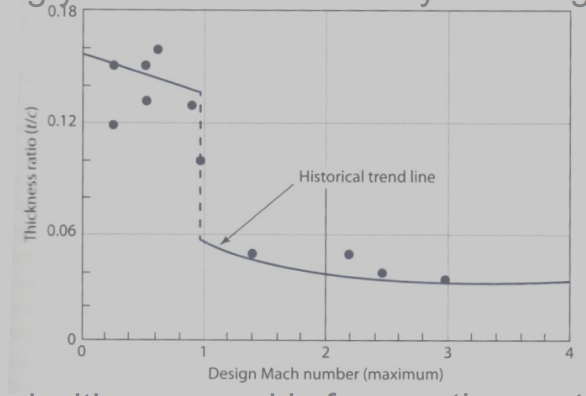

kA= 0.95;
Lambdades = 20*pi/180;
MDD = 0.85;

polarPath =  '../Airfoils/Airfoil polar data'; % Specify your directory path here
files = dir(polarPath); % Get a structure array with file information
polarNames = {files(~[files.isdir]).name}; % Extract names of all files, excluding directories

XYPath =  '../Airfoils/Airfoil XY data'; % Specify your directory path here
files = dir(XYPath); % Get a structure array with file information
XYNames = {files(~[files.isdir]).name}; % Extract names of all files, excluding directories
figure(4)
clf;
for i = 1:length(polarNames)
    thisairfoil = Airfoil();
    polarName = polarNames(i);
    shapeName = XYNames(i);
    thisairfoil = thisairfoil.readPolar(string(fullfile(polarPath, polarName)));
    thisairfoil = thisairfoil.readShape(string(fullfile(XYPath, shapeName)));
    thisairfoil = thisairfoil.interpShape(9);
    FF(i) = (1 + 0.6.*thisairfoil.t_c./thisairfoil.x_cm + 100 .*thisairfoil.t_c.^4) .* (1.34.*MDD.^0.18.*(cos(Lambdades)).^0.28);
    stallAngle(i) = thisairfoil.alphaSPos;
    CLmax(i) = max(thisairfoil.Cl);
    L_Ddes(i) = thisairfoil.L_DatCL(CLdesC1);
    t_c(i) = thisairfoil.t_c;
end

airfoilIdx = CLmax.*L_Ddes

airfoilIdx =    67.4807   68.9838   74.8436   85.4821   92.0619  107.0470  104.0407  114.4660  121.2740   53.3781  120.9334  134.6351  128.5125  102.6098  140.1716


airfoilData = table(polarNames', FF', t_c', stallAngle'.*180/pi, CLmax', L_Ddes', airfoilIdx', 'VariableNames', {'Name', 'Skin Friction Form Factor', 't/c', 'stallAngle','Clmax', 'L/D design', 'CLmax x L/D design'})

airfoilData = 15×7 table
                Name                 Skin Friction Form Factor      t/c       stallAngle    Clmax     L/D design    CLmax x L/D design
    _____________________________    _________________________    ________    __________    ______    __________    __________________

    {'xf-sc20010-il-1000000.csv'}              1.501               0.10003      13.75       1.2817      52.649            67.481      
    {'xf-sc20012-il-1000000.csv'}             1.5566               0.12003      15.25       1.3893      49.654            68.984      
    {'xf-sc20410-il-1000000.csv'}             1.3218              0.020035      12.75       1.4554      51.425            74.844      
    {'xf-sc20412-il-1000000.csv'}             1.3457         

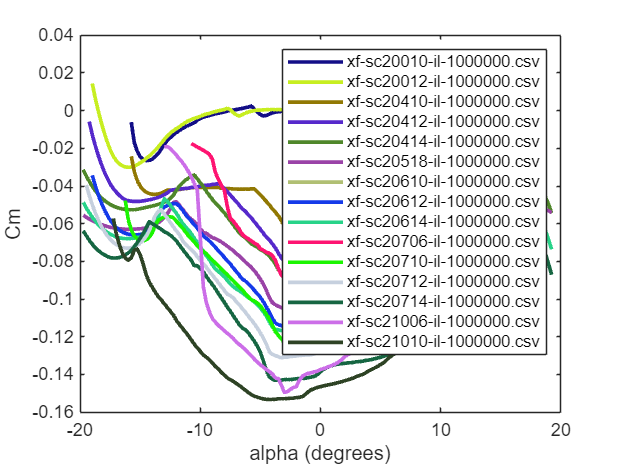

figure(7)
clf;
for i = 1:length(polarNames)
    thisairfoil = Airfoil();
    polarName = polarNames(i);
    shapeName = XYNames(i);
    thisairfoil = thisairfoil.readPolar(string(fullfile(polarPath, polarName)));
    thisairfoil = thisairfoil.readShape(string(fullfile(XYPath, shapeName)));
    thisairfoil = thisairfoil.interpShape(9);
    randomColor = rand(1, 3); % Generate a random RGB color
    plot(thisairfoil.alpha.*180/pi,thisairfoil.Cm,'LineWidth',2, 'Color', randomColor)
    hold on
end
legend(polarNames)
xlabel("alpha (degrees)")
ylabel("Cm")

t_cSweep = @(kA, Lambda, MDD, CL) cos(Lambda).*(kA - MDD.*cos(Lambda) - CL./(10.*cos(Lambda).^2))

t_cSweep = function_handle with value:
    @(kA,Lambda,MDD,CL)cos(Lambda).*(kA-MDD.*cos(Lambda)-CL./(10.*cos(Lambda).^2))


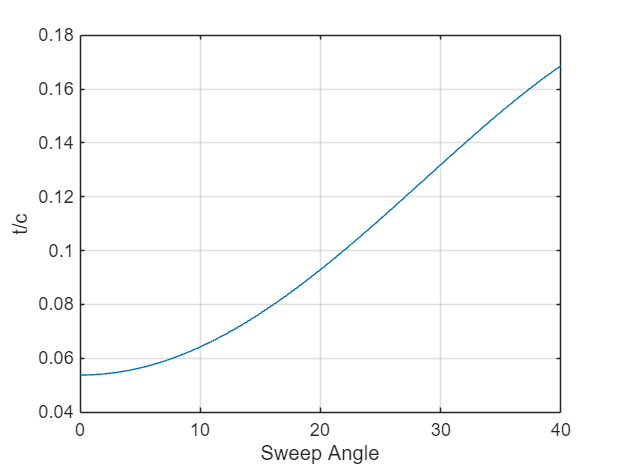

figure;
Lrange = linspace(0,40,100)*pi/180;
plot(Lrange*180/pi, t_cSweep(0.95,Lrange, 0.85, CLdesC1))
xlabel("Sweep Angle")
ylabel("t/c")
grid on

### Conclusion:

polarName = "xf-sc21010-il-1000000.csv";
shapeName = "sc21010.dat.txt";
airfoil = Airfoil();
airfoil = airfoil.readPolar(string(fullfile(polarPath, polarName)));
airfoil = airfoil.readShape(string(fullfile(XYPath, shapeName)));
airfoil = airfoil.interpShape(9);

## 3.Shape

1.Use MDO to get best geometry

    -Make sure it is applicable to double-tapered, swept wing

    -At each iteration inside MDO, calculate the optimum twist to give elliptical lift distribution

    -Use a validated wing weight estimation model

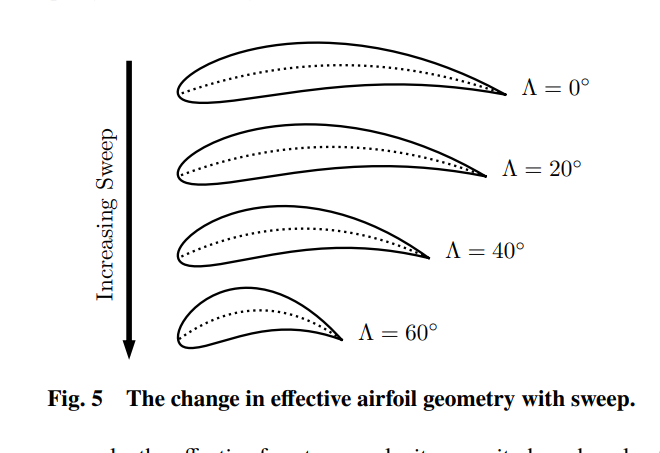

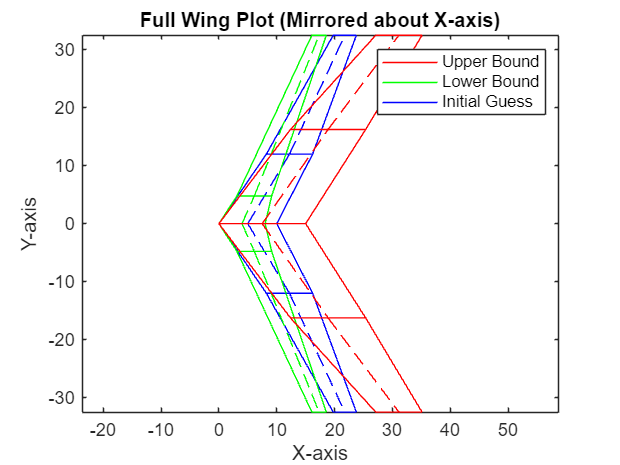


% Initial guess
% wing span fixed to 65
bdes = 65;
x0 = [10, 8, 4, 31*pi/180, 25*pi/180, 12, deg2rad(1.3)];
%x0 = [cr, ck, ct, Lambdain50, Lambdaout50, yk, maxtwist in radians]
% Design variables 
%lb = x0.*0.5;
%ub = x0.*2;
lb = [8, 6, 2.5, 24*pi/180, 22*pi/180, bodyDiameter/2 * 1.5, deg2rad(0)];
ub = [15, 13, 8, 35*pi/180, 37*pi/180, bdes/2*0.5, deg2rad(5)];
wing0 = x2wing(x0);
winglb = x2wing(lb);
wingub = x2wing(ub);
figure(1)
clf;
wing0.plotWing('b')
hold on
winglb.plotWing('g')
hold on
wingub.plotWing('r')
hold on
h1 = plot(NaN, NaN, 'r', 'DisplayName', 'Upper Bound');
hold on
h2 = plot(NaN, NaN, 'g', 'DisplayName', 'Lower Bound');
hold on
h3 = plot(NaN, NaN, 'b', 'DisplayName', 'Initial Guess');
hold off;

% Create the legend
legend([h1, h2, h3]);

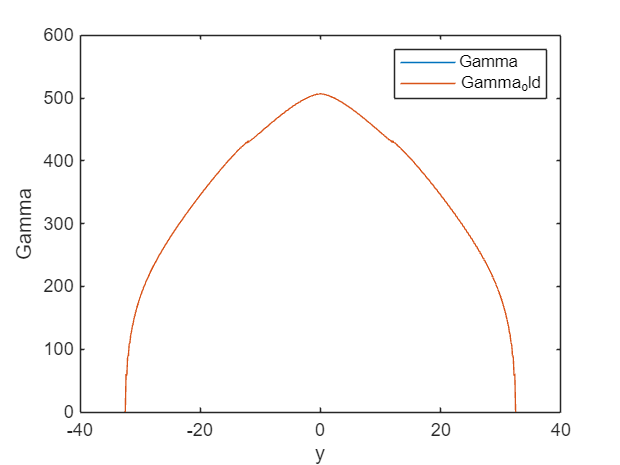

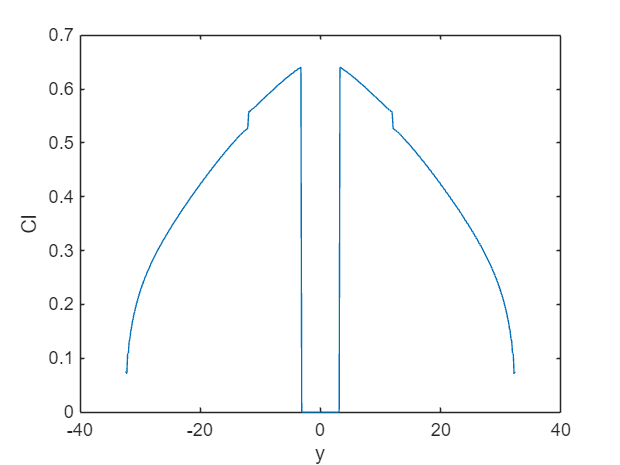

CL = 0.4198

CD = 0.0077

CLy =   -32.5000  -32.3700  -32.2400  -32.1100  -31.9800  -31.8500  -31.7200  -31.5900  -31.4600  -31.3300  -31.2000  -31.0700  -30.9400  -30.8100  -30.6800  -30.5500  -30.4200  -30.2900  -30.1600  -30.0300  -29.9000  -29.7700  -29.6400  -29.5100  -29.3800  -29.2500  -29.1200  -28.9900  -28.8600  -28.7300  -28.6000  -28.4700  -28.3400  -28.2100  -28.0800  -27.9500  -27.8200  -27.6900  -27.5600  -27.4300  -27.3000  -27.1700  -27.0400  -26.9100  -26.7800  -26.6500  -26.5200  -26.3900  -26.2600  -26.1300
    0.0738    0.0747    0.0711    0.1084    0.1097    0.1320    0.1363    0.1510    0.1565    0.1671    0.1729    0.1811    0.1868    0.1935    0.1989    0.2047    0.2097    0.2148    0.2195    0.2242    0.2285    0.2328    0.2369    0.2409    0.2448    0.2486    0.2522    0.2558    0.2593    0.2627    0.2660    0.2693    0.2725    0.2756    0.2787    0.2817    0.2847    0.2876    0.2905    0.2934    0.2962    0.2990    0.3017    0.3044    0.3071    0.3097    0.3123    0.3149    0.3175   


cruise1 = cruise1.init(wing0.cbar);
Wto = Wto0;
[CL, CD, CLy] = LLESwept(wing0, airfoil, cruise1)

Ww = wingWeightRaymer(wing0,airfoil,Wto,nult,wing0.SREF*0.0612);
W_ZF_Nowing = Wto - Ww - Wto*0.4573 - Wpayload;
W_ZF_Nowing = W_ZF_Nowing* 0.99;
disp(["Structural mass without wing [kg]: ", W_ZF_Nowing/9.81])

    "Structural mass without wing [kg]: "    "185623.0613"



    "L/D cruise 1 = "    "14.0446"

    "L/D cruise 2 = "    "14.7192"

    "Fuel fraction: "    "0.49545"

    "Ww = "    "363863.5757"

    "Wto = "    "4499712.5517"

    "L/D cruise 1 = "    "14.0446"

    "L/D cruise 2 = "    "14.7192"

    "Fuel fraction: "    "0.49545"

    "Ww = "    "377239.5313"

    "Wto = "    "4526223.0349"

    "L/D cruise 1 = "    "14.0446"

    "L/D cruise 2 = "    "14.7192"

    "Fuel fraction: "    "0.49545"

    "Ww = "    "378475.8767"

    "Wto = "    "4528673.4109"

    "L/D cruise 1 = "    "14.0446"

    "L/D cruise 2 = "    "14.7192"

    "Fuel fraction: "    "0.49545"

    "Ww = "    "378589.9905"

    "Wto = "    "4528899.5788"

    "L/D cruise 1 = "    "14.0446"

    "L/D cruise 2 = "    "14.7192"

    "Fuel fraction: "    "0.49545"

    "Ww = "    "378600.5224"

    "Wto = "    "4528920.4481"

    "L/D cruise 1 = "    "14.0446"

    "L/D cruise 2 = "    "14.7192"

    "Fuel fraction: "    "0.49545"

    "Ww = "    "378601.4941"

    "Wto = "

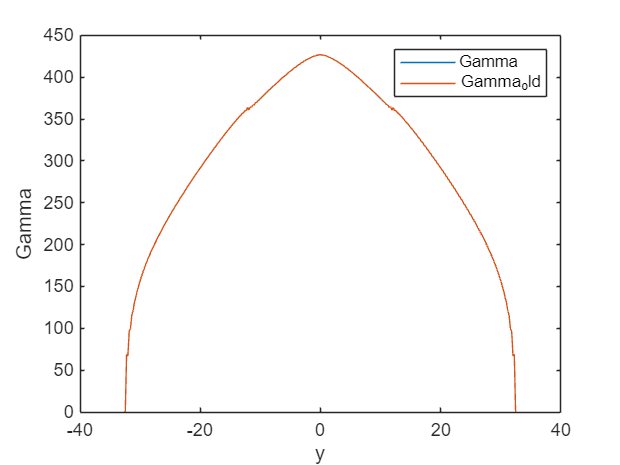

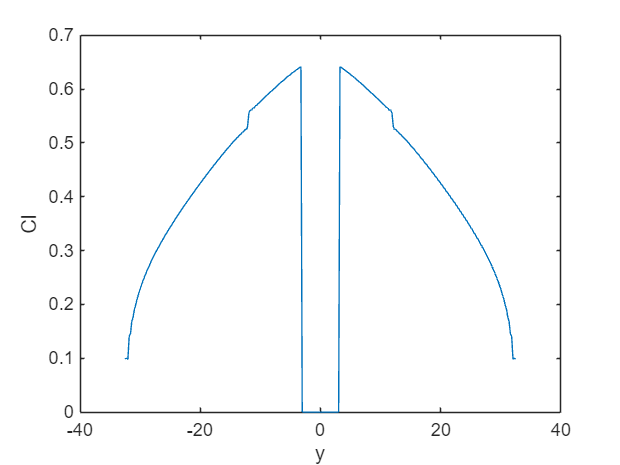

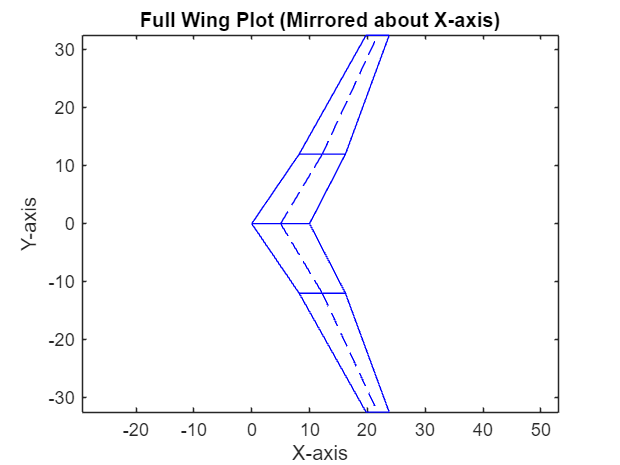

%wingMDO(x0)
% Optimization options
options = optimoptions('fmincon', ...
    'Algorithm', 'sqp', ...
    'Display', 'iter', ...
    'SpecifyObjectiveGradient', false, ...
    'SpecifyConstraintGradient', false, ...
    'UseParallel', false);
% Run the optimization
[x_opt, fval] = fmincon(@wingMDO, x0, [], [], [], [], lb, ub, @constraintFunction, options);

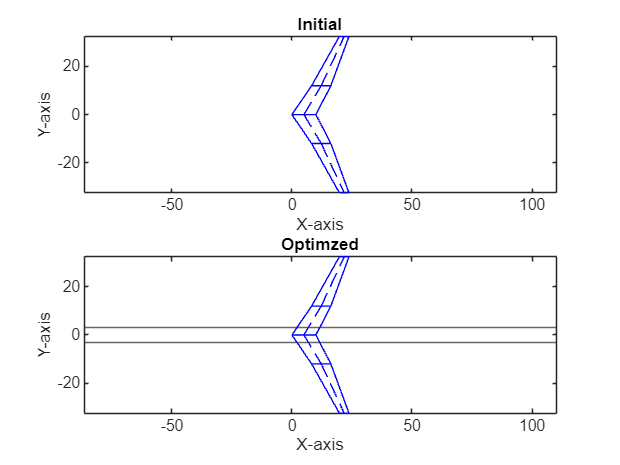

wing_opt =  x2wing(x_opt);
wing_opt = wing_opt.calcSref();
figure(1)
clf;
subplot(2,1,1)
wing0.plotWing()
title("Initial")
axis equal
subplot(2,1,2)
wing_opt.plotWing()
title("Optimzed")
yline(bodyDiameter/2)
hold on
yline(-bodyDiameter/2)
axis equal


save("wing_opt.mat","wing_opt")

Analyse the aero characteristic of opt wing:

During cruise1:

%load("wing_opt.mat")
cruise1 = cruise1.init(wing_opt.cbar)

cruise1 =   AirCondition with properties:

      M: 0.8300
      V: 244.9078
      h: 1.1582e+04
    rho: 0.3320
      T: 216.6500
      a: 295.0696
      P: 2.0646e+04
     nu: 4.2822e-05
     mu: 1.4216e-05
     Re: 4.2894e+07


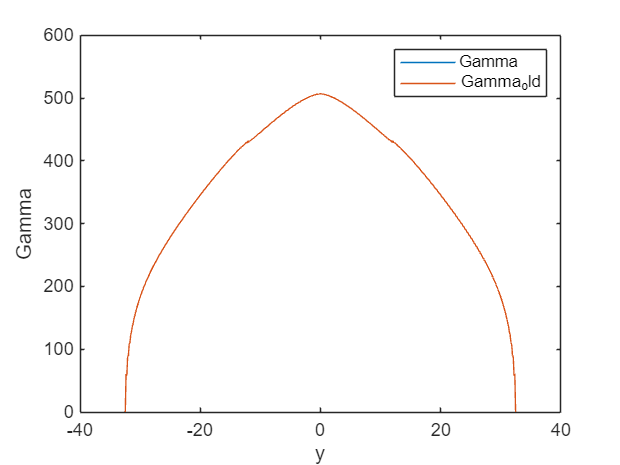

CL1 = 0.4198

CDi1 = 0.0077

Cly1 =   -32.5000  -32.3700  -32.2400  -32.1100  -31.9800  -31.8500  -31.7200  -31.5900  -31.4600  -31.3300  -31.2000  -31.0700  -30.9400  -30.8100  -30.6800  -30.5500  -30.4200  -30.2900  -30.1600  -30.0300  -29.9000  -29.7700  -29.6400  -29.5100  -29.3800  -29.2500  -29.1200  -28.9900  -28.8600  -28.7300  -28.6000  -28.4700  -28.3400  -28.2100  -28.0800  -27.9500  -27.8200  -27.6900  -27.5600  -27.4300  -27.3000  -27.1700  -27.0400  -26.9100  -26.7800  -26.6500  -26.5200  -26.3900  -26.2600  -26.1300
    0.0738    0.0747    0.0711    0.1084    0.1097    0.1320    0.1363    0.1510    0.1565    0.1671    0.1729    0.1811    0.1868    0.1935    0.1989    0.2047    0.2097    0.2148    0.2195    0.2242    0.2285    0.2328    0.2369    0.2409    0.2448    0.2486    0.2522    0.2558    0.2593    0.2627    0.2660    0.2693    0.2725    0.2756    0.2787    0.2817    0.2847    0.2876    0.2905    0.2934    0.2962    0.2990    0.3017    0.3044    0.3071    0.3097    0.3123    0.3149    0.3175  

CDprofile1 = 0.0063

[CL1, CDi1, Cly1, CDprofile1] = LLESwept(wing_opt, airfoil, cruise1)

CDF1 = CDFfun(cruise1.M, cruise1.Re, wing_opt, airfoil.x_cm, airfoil.t_c, l_d, Swet_SrefWing, Swet_SrefBody);
CDW1 = CDWfun(wing_opt,Cly1,cruise1.M,airfoil.t_c);
CDtotal1 = CDF1 + CDW1 + CDi1 + CDprofile1;

disp(["L/D opt: ", CL1/ CDtotal1])

    "L/D opt: "    "14.1375"



disp(["CLclean opt: ", CL1])

    "CLclean opt: "    "0.41977"



disp(["Sref opt: ", wing_opt.SREF])

    "Sref opt: "    "462"



disp(["Maximum twist(degrees) opt", wing_opt.twist_max * 180/pi])

    "Maximum twist(degrees) opt"    "1.3"



disp(["Inner sweep angle(degrees) opt", wing_opt.Lambdain50 * 180/pi])

    "Inner sweep angle(degrees) opt"    "31"



disp(["Outer sweep angle(degrees) opt", wing_opt.Lambdaout50 * 180/pi])

    "Outer sweep angle(degrees) opt"    "25"



disp(wing_opt)

  WingGeometry with properties:

             cr: 10
             ck: 8
             ct: 4
              s: 32.5000
             yk: 12
     Lambdain50: 0.5411
    Lambdaout50: 0.4363
              N: 501
             Sc: [0.2604 0.5233 0.5266 0.5299 0.5332 0.5365 0.5398 0.5431 0.5464 0.5497 0.5530 0.5563 0.5596 0.5629 0.5662 0.5695 0.5728 0.5761 0.5794 0.5827 0.5860 0.5892 0.5925 0.5958 0.5991 0.6024 0.6057 0.6090 0.6123 0.6156 0.6189 … ] (1×501 double)
         stripy: [-32.5000 -32.3700 -32.2400 -32.1100 -31.9800 -31.8500 -31.7200 -31.5900 -31.4600 -31.3300 -31.2000 -31.0700 -30.9400 -30.8100 -30.6800 -30.5500 -30.4200 -30.2900 -30.1600 -30.0300 -29.9000 -29.7700 -29.6400 -29.5100 … ] (1×501 double)
             AR: 9.1450
            Sin: 216
           Sout: 246
           cbar: 7.5000
              b: 65
           SREF: 462
      twist_max: 0.0227
             cn: [4.0000 4.0254 4.0507 4.0761 4.1015 4.1268 4


cruise1 = cruise1.init(wing0.cbar)

cruise1 =   AirCondition with properties:

      M: 0.8300
      V: 244.9078
      h: 1.1582e+04
    rho: 0.3320
      T: 216.6500
      a: 295.0696
      P: 2.0646e+04
     nu: 4.2822e-05
     mu: 1.4216e-05
     Re: 4.2894e+07


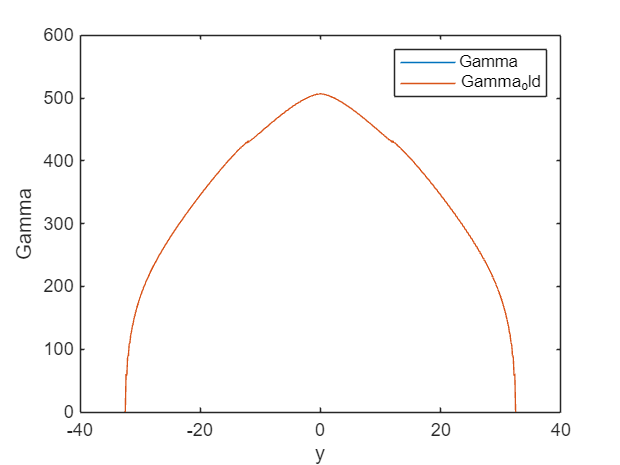

CL0 = 0.4198

CDi0 = 0.0077

Cly0 =   -32.5000  -32.3700  -32.2400  -32.1100  -31.9800  -31.8500  -31.7200  -31.5900  -31.4600  -31.3300  -31.2000  -31.0700  -30.9400  -30.8100  -30.6800  -30.5500  -30.4200  -30.2900  -30.1600  -30.0300  -29.9000  -29.7700  -29.6400  -29.5100  -29.3800  -29.2500  -29.1200  -28.9900  -28.8600  -28.7300  -28.6000  -28.4700  -28.3400  -28.2100  -28.0800  -27.9500  -27.8200  -27.6900  -27.5600  -27.4300  -27.3000  -27.1700  -27.0400  -26.9100  -26.7800  -26.6500  -26.5200  -26.3900  -26.2600  -26.1300
    0.0738    0.0747    0.0711    0.1084    0.1097    0.1320    0.1363    0.1510    0.1565    0.1671    0.1729    0.1811    0.1868    0.1935    0.1989    0.2047    0.2097    0.2148    0.2195    0.2242    0.2285    0.2328    0.2369    0.2409    0.2448    0.2486    0.2522    0.2558    0.2593    0.2627    0.2660    0.2693    0.2725    0.2756    0.2787    0.2817    0.2847    0.2876    0.2905    0.2934    0.2962    0.2990    0.3017    0.3044    0.3071    0.3097    0.3123    0.3149    0.3175  

CDprofile0 = 0.0063

[CL0, CDi0, Cly0, CDprofile0] = LLESwept(wing0, airfoil, cruise1)

CDF0 = CDFfun(cruise1.M, cruise1.Re, wing0, airfoil.x_cm, airfoil.t_c, l_d, Swet_SrefWing, Swet_SrefBody);
CDW0 = CDWfun(wing0,Cly1,cruise1.M,airfoil.t_c);
CDtotal0 = CDF0 + CDW0 + CDi0 + CDprofile0;
disp(["L/D 0: ", CL0/ CDtotal0])

    "L/D 0: "    "14.1375"



figure
clf;
Mrange = linspace(0.5,0.9,10)

Mrange =     0.5000    0.5444    0.5889    0.6333    0.6778    0.7222    0.7667    0.8111    0.8556    0.9000


for i = 1:length(Mrange)
    M = Mrange(i);
    cruise1 = cruise1.init(wing_opt.cbar);
    [CL1, CDi1, Cly1,CDprofile1] = LLESwept(wing_opt, airfoil, cruise1);
    CDW_opt(i) = CDWfun(wing_opt,Cly1,M,airfoil.t_c);
    cruise1 = cruise1.init(wing0.cbar);
    [CL0, CDi0, Cly0,CDprofile0] = LLESwept(wing0, airfoil, cruise1);
    CDW_0(i) = CDWfun(wing0,Cly0,M,airfoil.t_c);
end

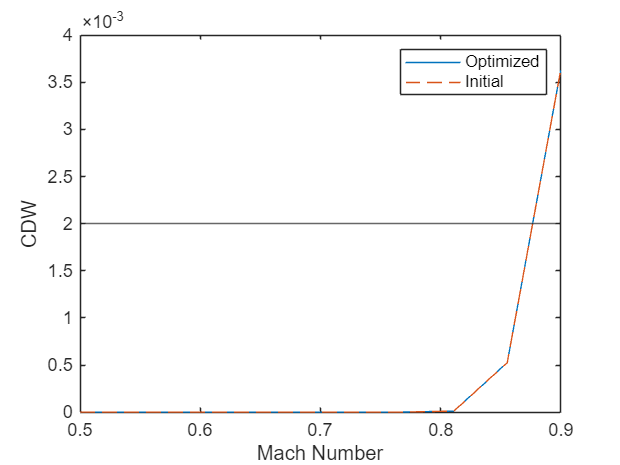

plot(Mrange, CDW_opt)
hold on
plot(Mrange, CDW_0,'--')
hold on
yline(0.002)
legend("Optimized","Initial")
ylabel("CDW")
xlabel("Mach Number")

## 4.Dihedral

-G17 presents a quantitative estimate

## 5.HLD

1.Calculate CLmax requirement at landing and takeoff

2.Select

## 6.Control Surfaces

## 7.Tailplane design

## 8.Nose shape optimization